nV = 100;
NE = nV * (nV - 1) / 2;

idx = 1:NE

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


d = ceil(idx/nV)

d =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


i = mod(idx-1,nV)+1

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


j = mod(idx+d-1,nV)+1

j =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


A = full(sparse(i,j,idx,nV,nV))

A =            0           1         101         201         301         401         501         601         701         801         901        1001        1101        1201        1301        1401        1501        1601        1701        1801        1901        2001        2101        2201        2301        2401        2501        2601        2701        2801        2901        3001        3101        3201        3301        3401        3501        3601        3701        3801        3901        4001        4101        4201        4301        4401        4501        4601        4701        4801
           0           0           2         102         202         302         402         502         602         702         802         902        1002        1102        1202        1302        1402        1502        1602        1702        1802        1902        2002        2102        2202        2302        2402        2502        2602        2702        2802        2902        300

A = A + A'

A =            0           1         101         201         301         401         501         601         701         801         901        1001        1101        1201        1301        1401        1501        1601        1701        1801        1901        2001        2101        2201        2301        2401        2501        2601        2701        2801        2901        3001        3101        3201        3301        3401        3501        3601        3701        3801        3901        4001        4101        4201        4301        4401        4501        4601        4701        4801
           1           0           2         102         202         302         402         502         602         702         802         902        1002        1102        1202        1302        1402        1502        1602        1702        1802        1902        2002        2102        2202        2302        2402        2502        2602        2702        2802        2902        300

nE = floor(NE/3);
idx = randperm(NE,nE)

idx =         4287         315        3013        3337        4272        3253        2338        2593        3542         421         760        4629         549        3853        3278         469        2358        1745        2953        3894        4193        3286        1186         867        2711        4809        1747         235        4780         507        1122        4511        2898        2372         103         476        4682        2881         364        2330        1892        4534        3099        4194         802        1340        2124        4274        2444        3979


d = ceil(idx/nV);
i = mod(idx-1,nV)+1;
j = mod(idx+d-1,nV)+1;
A = full(sparse(i,j,idx*0+1,nV,nV));
A = A + A'

A =      0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     1     0     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1     1     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     1     0     0     0     0     0     0     0     1     0     1     0     0     0     1     1     1     0     1     0     1     1     1     0     1     0     1     0     1     1     0     1     0     1     0
     0     0     0     0     1     1     0     1     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     1     1     0     0     1     1     0     0     1     1     0     1     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     1     0     1     0     1     0     1     1     1   

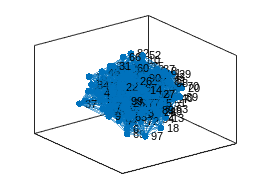

G = graph(A);
plot(G,'Layout','force3')